r = @(x) 100*(x(2)-x(1)^2)^2 + (1-x(1))^2;
g = @(x) x(1)*(x(1) + 3)*(x(1) - 3)*(x(1) - 5) + x(2)*(x(2) + 3)*(x(2) - 3)*(x(2) - 5);
f = @(x) ((x(1))^2 - 100)*((x(1))^2 - 61) + ((x(2))^2 - 25)*((x(2))^2 - 16) - 15*cos(x(1)-(7/5))*cos(x(2)-(9/2));

Nvar = 2;
Nmax = 50;
errodf = 0.15;
NPontosIniciais = 7

NPontosIniciais = 7

x_values=[-11;-11];y_values=[7;7];
% lambda = 0.00001;

%% Chamada da função newton_raphson
% [Lista, LNit, Lopt] = newton_raphson(r, Nmax, errodf, NPontosIniciais, x_values, y_values, lambda);
% [Lista, LNit, Lopt] = newton_raphson(g, Nvar, Nmax, errodf, NPontosIniciais, x_values, y_values, lambda);
[Lista, LNit, Lopt] = newton_raphson(g, Nvar, Nmax, errodf, NPontosIniciais, x_values, y_values)

Lista =    -0.6462   -6.4232   -4.1564   -2.7980   -2.1120   -1.8938   -1.8709   -6.7740   -4.3758   -2.9224   -2.1653   -1.9041   -1.8711    3.7815    4.3111    4.1907    4.1829    4.1828    4.1828    4.1828  -10.2256   -6.5870   -4.2587   -2.8557   -2.1363   -1.8983   -1.8710    0.6841    0.6841    0.6841    0.6841    0.6841    0.6841    0.6841    0.6841    0.6841    0.6841    0.6841    0.6841    0.6841    0.6841    0.6841    0.6841    0.6841    0.6841    0.6841    0.6841    0.6841    0.6841    0.6841
   -9.9240   -7.2745   -4.6913   -3.1049   -2.2484   -1.9231   -1.8719   -4.6431   -3.0768   -2.2353   -1.9199   -1.8717   -1.8706  -10.7227   -6.9102   -4.4614   -2.9715   -2.1871   -1.9088   -1.8713   -7.9582   -5.1258   -3.3621   -2.3733   -1.9574   -1.8739   -1.8706    2.1710    2.1710    2.1710    2.1710    2.1710    2.1710    2.1710    2.1710    2.1710    2.1710    2.1710    2.1710    2.1710    2.1710    2.1710    2.1710    2.1710    2.1710    2.1710    2.1710    2.1710    2.1710 

LNit =      7     6     7     7    50     4     6


Lopt =    -1.8709   -1.8711    4.1828   -1.8710    0.6841    1.4378   -1.8706
   -1.8719   -1.8706   -1.8713   -1.8706    2.1710   -1.8710   -1.8707


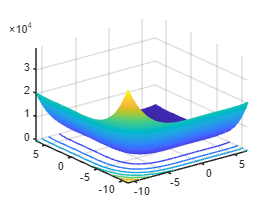


close all

nivelGraficos(g,x_values(1),y_values(1),x_values(2),y_values(2))

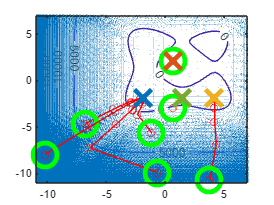


hold on

graficosLineSearch(Lista,LNit,Lopt)

hold off